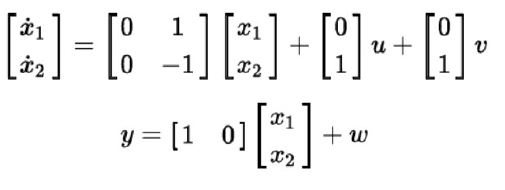

clc; clear; close all;
m  = 1;
c  = 1;
A  = [0 1; 0 -c/m];
B  = [0 1/m]';
C  = [1 0];
D  = 0;
Rproc = 0.1;
Rw = 0.01;
Rv = [0 0; 0 Rproc];

- Encuentre el valor de la matriz de covarianza P al resolver la ecuación de Ricatti correspondiente.

- Encuentre el valor de la matriz de ganancia de observación L.

[P,L,polos] = icare(A', C', Rv, Rw, [], [], []);
P = P'

P =     0.0171    0.0146
    0.0146    0.0394


L = L'

L =     1.7064
    1.4559


polos

polos =   -1.3532 + 1.1537i
  -1.3532 - 1.1537i


- Si se aumenta el ruido de proceso Rv, qué pasa con polos del estimador a lazo cerrado (sI-A+LC), ¿Se vuelven más rápidos, más lentos o no varían?.

for i = 1:1000
    Rproc = 0.1*(1 + i/100);
    Rv = [0 0; 0 Rproc];
    [~, ~, p] = icare(A', C', Rv, Rw, [], [], []);
    polos(i, 1:2) = p;
end
% Rv = [0 0; 0 Rproc];
% [P, L, polos] = icare(A', C', Rv, Rw, [], [], []);

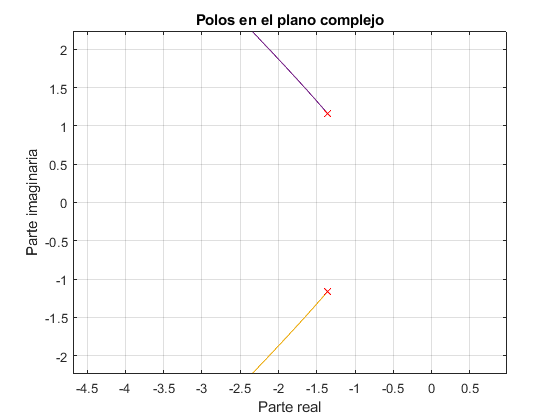

figure;
x = real(polos(1:end, :));
y = imag(polos(1:end, :));

plot(x, y, x, -y, 'LineWidth', 0.2);hold on;
plot(x(1), y(1), 'rx');
plot(x(1), -y(1), 'rx');
xlabel('Parte real');
ylabel('Parte imaginaria');
title('Polos en el plano complejo');
grid on;
axis equal;